Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 7 -- DFT of Data

%{
    This will be a script that will solve the problems in assigment 7 for
    Digital Signal Processing.

    Sam Kramer
    Feb 22nd, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

### Problem Description:

In the lecture today, I spent considerable time discussing the importance of understanding the indexing and the processing to obtain the spectral information. 

- Create a data vector of a 50 Hz(cosine, amplitude 1.2) that is periodic in the data vector. Use a sample rate of 1000 samples/sec for 0.5 sec.  Write a script that will calculate the cm from m=0 to 500. Plot the results in a presentation plot. (amplitude verses frequency)

- Create another vector with a cosine and sine component of equal amplitude. Plot the result similar to question 1, show the phase as well as amplitude

To find the Discrete Fourier Transform, I will use the equation provided in the notes below:

### 
$$C_m =\frac{1}{N}\sum_{n=1}^N f\left(n\right)e^{\frac{-2\pi \textrm{mnj}}{N}}$$


This calculates the discrete imaginary amplitude at the specific frequency of m$\omega$ and can be calculated for a value of m = 0 to N/2 before parameterization errors appear.

### Single Frequency Cosine:

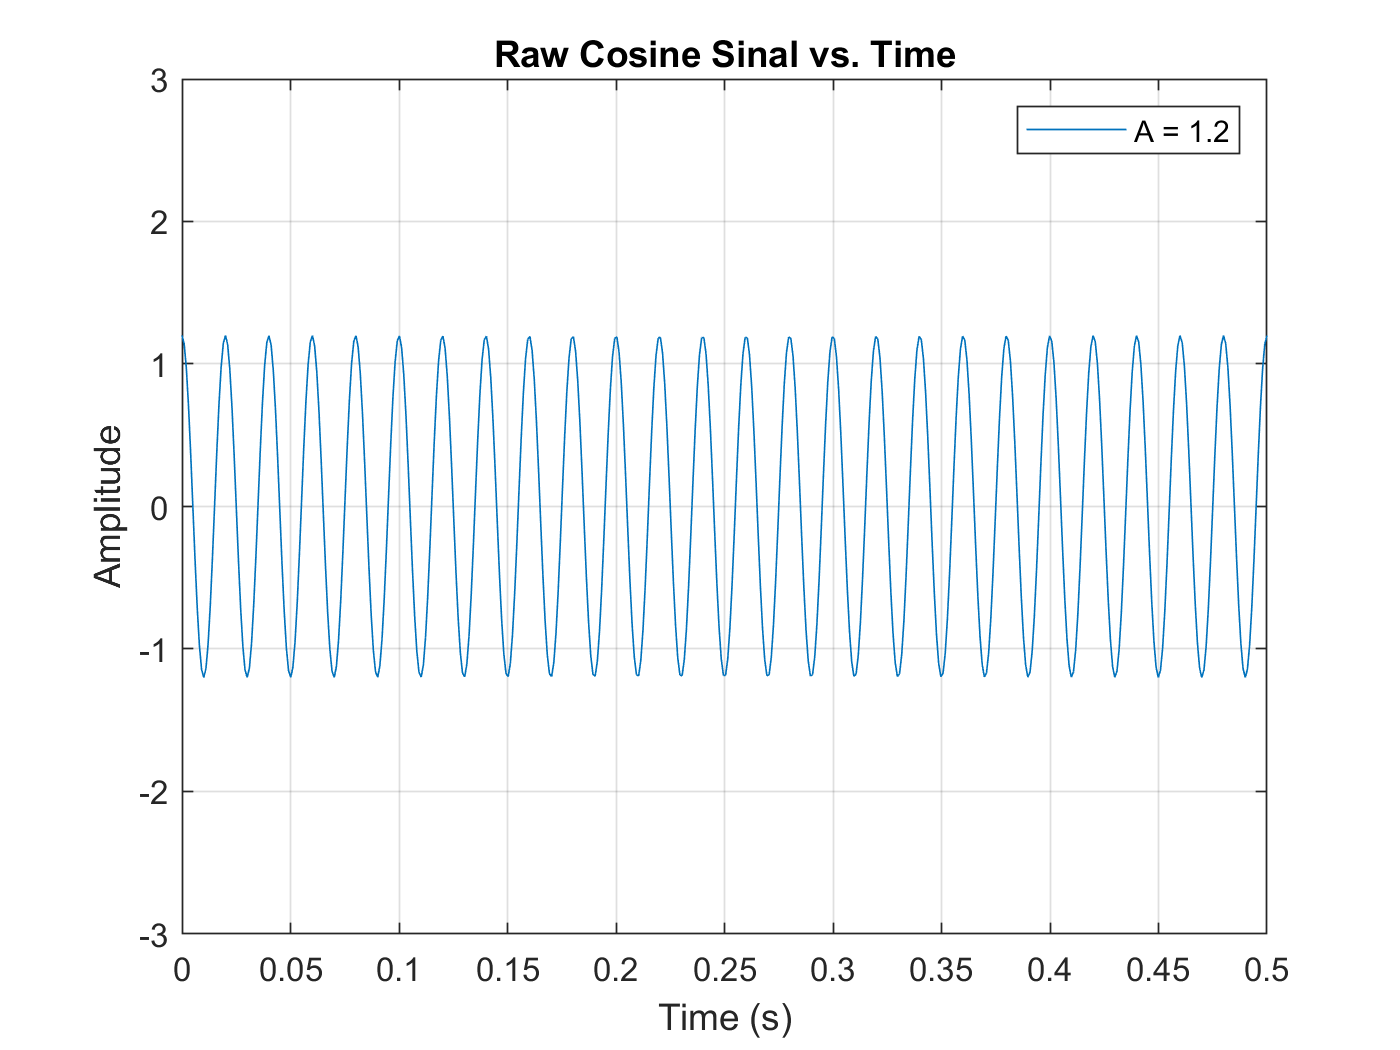

% --Parameters
    T = 0.5;                                    % Period;
    N = 1000*T;                                 % Sample frequency (fs/2)
    time = linspace(0,T,N);                     % Time vector
    amplitude = 1.2;                            % Cosine amplitude
    frequency = 50;                             % frequency of cosine (Hz)
    
    
% --Calculate Cosine wave
    frequency = frequency * 2 * pi;             % frequency (rad/s)
    wave = amplitude* cos(frequency .* time);   % Cosine wave
    
    % --Plot wave
        figure (1)
        plot(time,wave)
            ylim([-3 3])
            xlabel('Time (s)')
            ylabel('Amplitude')
            title('Raw Cosine Sinal vs. Time')
            legend('A = 1.2')
            grid on

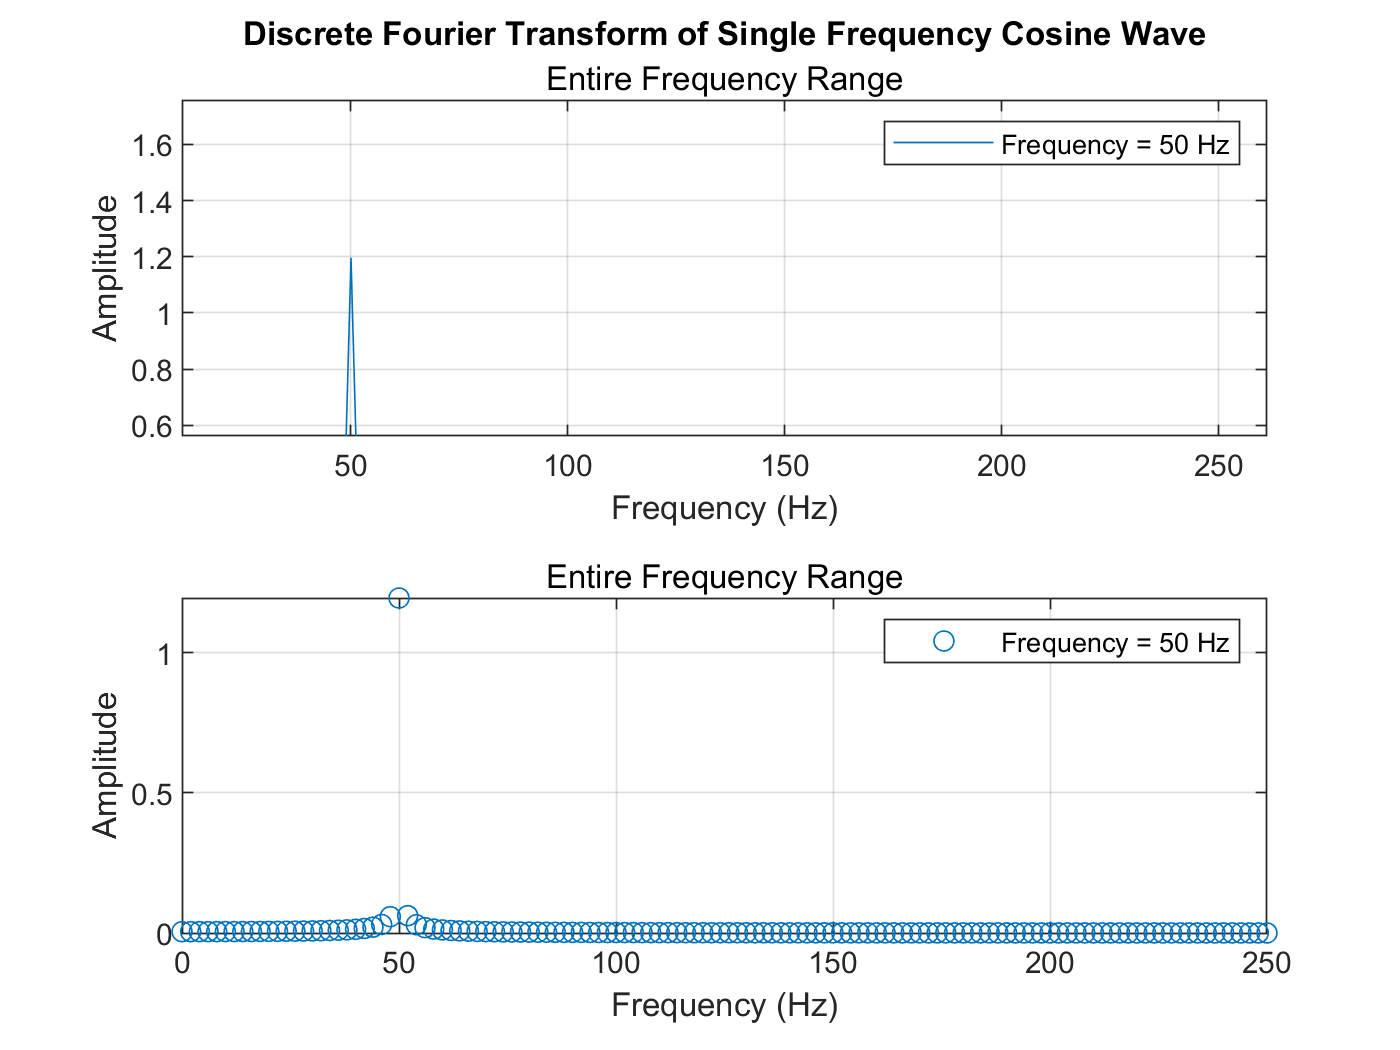

            hold on

% --Format problem
        sol_magnitude = [];                     % Solution vector
        n = 0:N - 1;                            % Temporal index   
        
% --Calculate the DFT of the raw cosine signal
    for m = 0:N-1              % Frequency index
        
        % --First exponent term
            term_1 = (exp((-1i*2*pi*m*n)/N))';
            
        % --Complete Cm calculation
            Cm = sum(wave * term_1);
            
        % --Calculate magnitude
            Cm = 2*abs(Cm)/(N);
        
        % --Save values
            sol_magnitude = [sol_magnitude, Cm];
        
    end
    
% --reformat frequency
    magnitude = sol_magnitude(1:N/2);
    freq = 0:(1/T):(N) - (1/T);
    
% --Plot 
    figure(2)
    subplot(2,1,1)
    plot(freq,magnitude)
        xlim([0 250])
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        title('Discrete Fourier Transform of Single Frequency Cosine Wave')
        subtitle('Entire Frequency Range')
        grid on
        legend('Frequency = 50 Hz')
    
    subplot(2,1,2)
    plot(freq,magnitude,'o')
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        subtitle('Entire Frequency Range')
        grid on
        legend('Frequency = 50 Hz')

        xlim([0 250])

### Sine and Cosine Wave Signal:

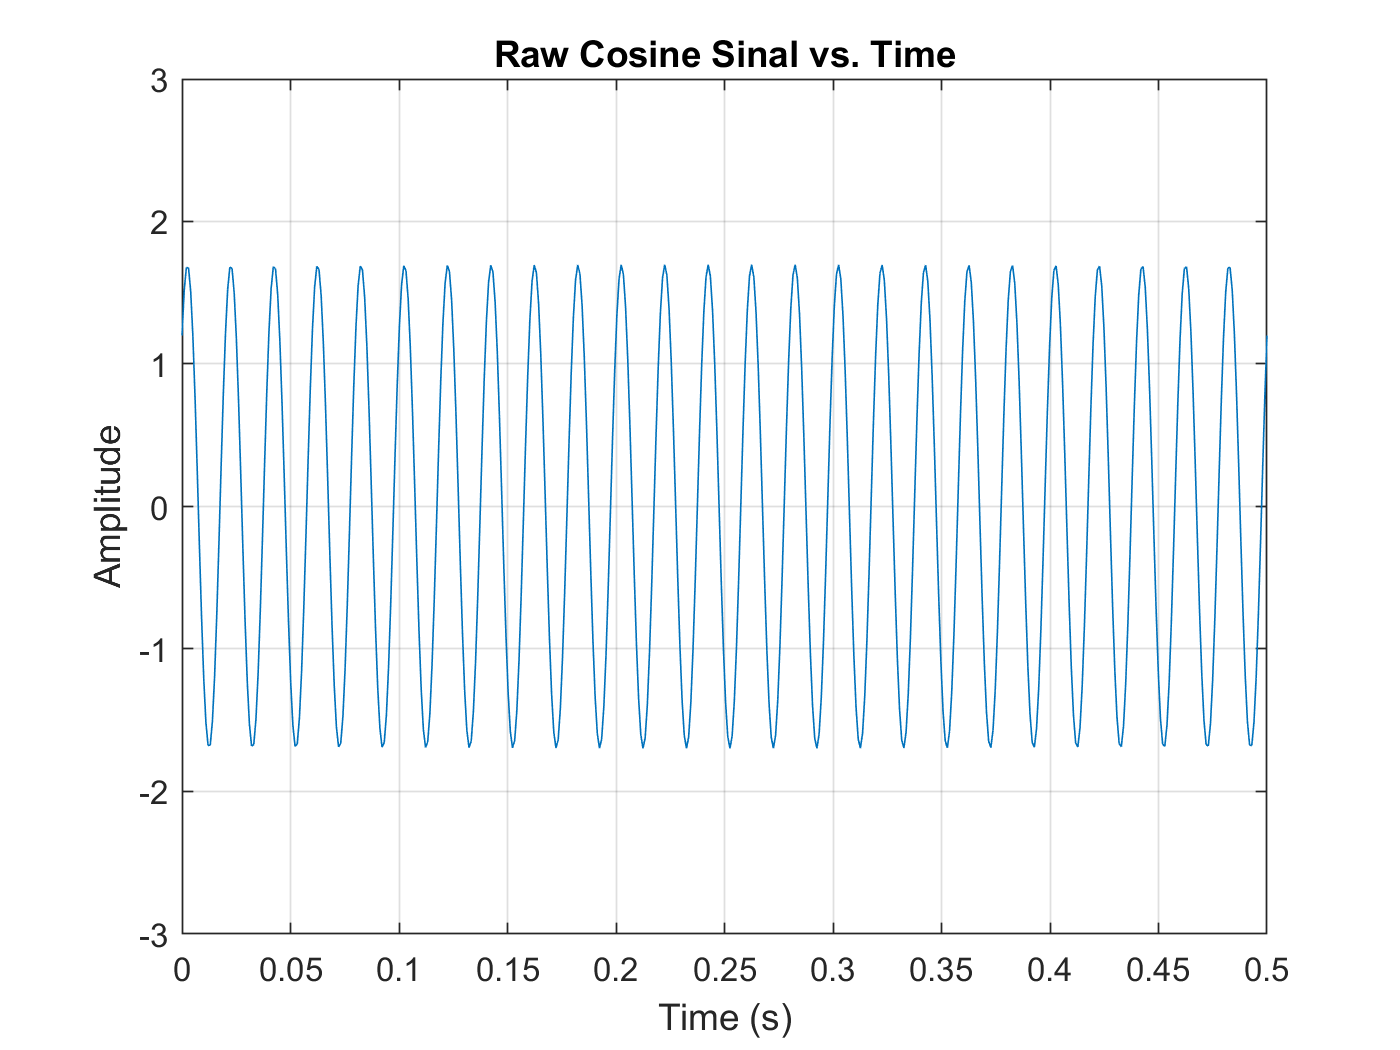

% --Calculate wave
    cosine = amplitude * cos(frequency .* time);    % Cosine wave
    sine = amplitude * sin(frequency .* time);      % Sine wave
    wave = sine + cosine;                           % Wave equation
    
    % --Plot wave
        figure (3)
        plot(time,wave)
            xlabel('Time (s)')
            ylabel('Amplitude')
            title('Raw Cosine Sinal vs. Time')
            grid on
            hold on
            ylim([-3 3])

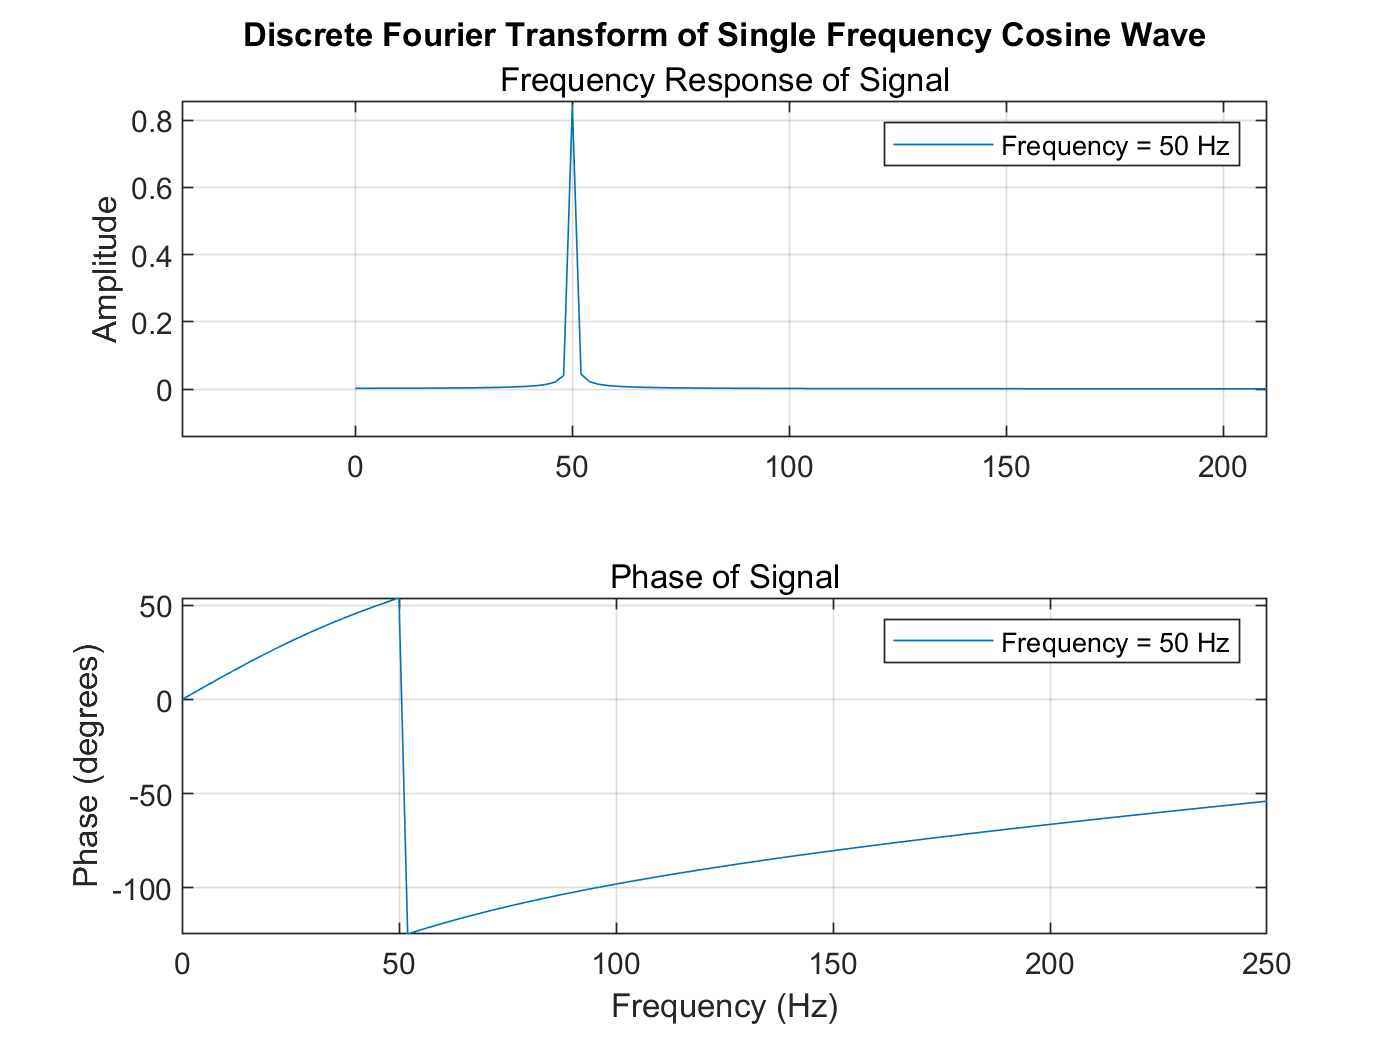


% --Format problem
        sol_magnitude = [];                     % Solution vector
        sol_phase = [];                         % Phase solution vector
        n = 1:N;                                % Temporal index
        dt = 1/N;                               % Time step
    
% --Calculate the DFT of the raw cosine signal
    for m = 0:N - 1     % Frequency index
        
        % --First exponent term
            term_1 = (exp((-1i*2*pi*m*n)/N))';
            
        % --Complete Cm calculation
            Cm = sum(wave * term_1);
            Cm = Cm/N;
            
        % --Calculate magnitude
            magnitude = abs(Cm);
            phase = atan2d(imag(Cm),real(Cm));
            
        % --Save values
            sol_magnitude = [sol_magnitude, magnitude];
            sol_phase = [sol_phase phase];
        
    end
    
% --reformat frequency
    magnitude = sol_magnitude(1:N/2);
    phase = sol_phase(1:N/2);
    freq = 0:(1/T):(N) - (1/T);
    
% --Plot 
    figure(4)
    subplot(2,1,1)
    plot(freq,magnitude)
        xlim([0 250])
        ylabel('Amplitude')
        title('Discrete Fourier Transform of Single Frequency Cosine Wave')
        subtitle('Frequency Response of Signal')
        grid on
        legend('Frequency = 50 Hz')
    
    subplot(2,1,2)
    plot(freq,phase)
        ylabel('Phase (degrees)')
        xlabel('Frequency (Hz)')
        subtitle('Phase of Signal')
        grid on
        legend('Frequency = 50 Hz')
        xlim([0 250])

### Analysis of Data:

    If we look at the data that we created from the discrete fourier transform of the data we can see that the peak of the frequency response is at 25 Hz. This is because of the period that was used for the time vector of original periodic signal. This comes at the cost of the assumption that we made when we transformed the normalization over the period to be equivalent to the time step times the number of samples. In order to verify that this was what causes the error, I ran one test where the time vector of the signal ended at one second and the peak appeared at the 50Hz mark. This is the consequence of one of the assumptions that we made when we described the discrete fourier transform equation. 